initSim

Cbase1v = 0.0150

l_f = 0.0265

r_f = 0.0063

SCR_grid = 5

z_grid = 0.2000

r_grid = 0.0632

x_grid = 0.1897

l_grid = 6.0395e-04

R_mv = 0.6000

L_mv = 0.0034

R_grid = 2.2588

L_grid = 0.0216

x_mv_tot = 113.2518

x_hv_tot = 18.8496

r_mv_tot = 0.0912

r_hv_tot = 0.0013

ans = 1.4293e+03

k_p_p_vsm = 0.6000

k_p_q_vsm = -0.0500

k_d_vsm = 70

H_vsm = 3

ki_q = 314.1593

V_dc_base = 1.1268e+03

V_dc = 1.1268e+03

C_dc = 0.0236

ans = 1.5708

I_dc_base = 1.3312e+03

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


L_f = l_f%*Lbase1v

L_f = 0.0265

R_f = r_f%*Zbase1v

R_f = 0.0063

C_f = 0.0757204%*Cbase1v

C_f = 0.0757

c_f = 0.0757

c_f = 0.0757

% plant
    
G_plant = 1/(s*L_f)

G_plant =
 
     1
  --------
  0.0265 s
 
Continuous-time transfer function.
Model Properties


T_delay = 0.1e-3

T_delay = 1.0000e-04

G_sensor = 1/(1+s*T_delay)

G_sensor =
 
       1
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.
Model Properties


G_i = G_plant*G_sensor

G_i =
 
             1
  -----------------------
  2.65e-06 s^2 + 0.0265 s
 
Continuous-time transfer function.
Model Properties



f_sw = 10000

f_sw = 10000

f_c = 1/20*f_sw

f_c = 500



Kp_cc =  0.06      

Kp_cc = 0.0600

Ti_cc =  0.0013

Ti_cc = 0.0013

% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)  
G_cc = Kp_cc*(1 + s*Ti_cc)/(s*Ti_cc)

G_cc =
 
  7.8e-05 s + 0.06
  ----------------
      0.0013 s
 
Continuous-time transfer function.
Model Properties


Kp_cc*(1+1/Ti_cc/s)

ans =
 
  0.06 s + 46.15
  --------------
        s
 
Continuous-time transfer function.
Model Properties



Ki_cc = Kp_cc/Ti_cc

Ki_cc = 46.1538


Kp_cc+Ki_cc/s

ans =
 
  0.06 s + 46.15
  --------------
        s
 
Continuous-time transfer function.
Model Properties



G_openl = G_cc*G_i

G_openl =
 
        7.8e-05 s + 0.06
  -----------------------------
  3.445e-09 s^3 + 3.445e-05 s^2
 
Continuous-time transfer function.
Model Properties


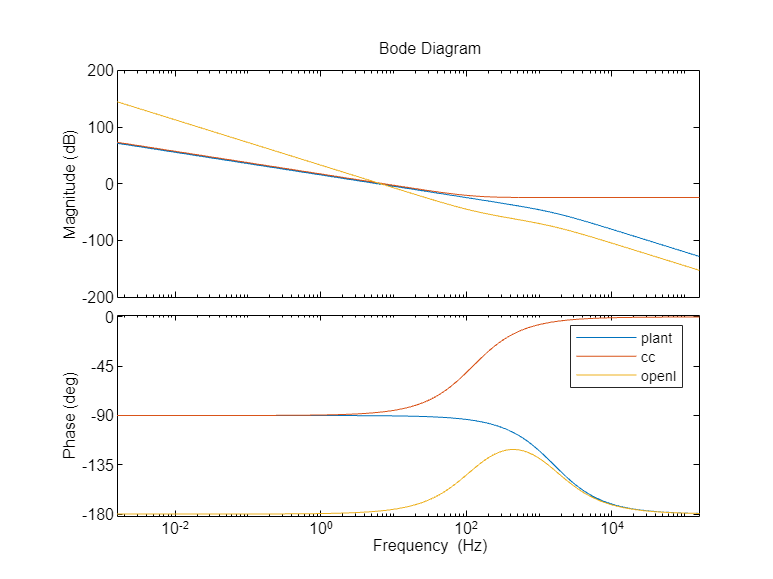



options = bodeoptions;
options.FreqUnits = 'Hz'; % or 'rad/second', 'rpm', etc.
options.PhaseWrapping='on';


bode(G_i,G_cc,G_openl,{10e-3,10e5}, options)
legend('plant', 'cc','openl')

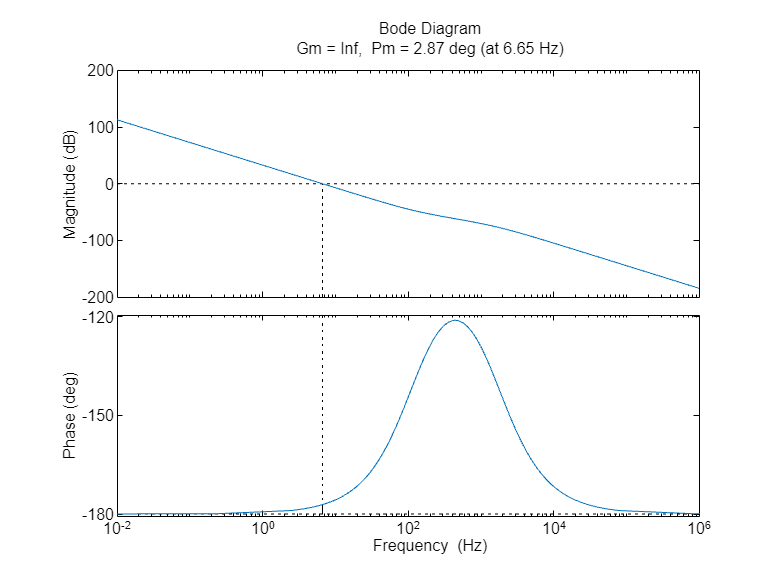

% bode(G_cc/(1+G_cc),{10e-3,10e5})

options.XLim = [10e-3,10e5];
% 
margin(G_openl,options)

% margin(G_cl)
% step(G_cl)
% pzmap(G_cl)

T_ers = 1/(2*pi*f_c)

T_ers = 3.1831e-04

Gapprox = 1/(1+s*T_ers)

Gapprox =
 
         1
  ---------------
  0.0003183 s + 1
 
Continuous-time transfer function.
Model Properties



P0 = Sbase1

P0 = 1500000

p_1 = -1/T_ers

p_1 = -3.1416e+03

z_1 = 3*Vbase_lv^2/(2*L_f*P0)

z_1 = 11.9774

UDC = V_dc

UDC = 1.1268e+03

UNd = Vbase_lv

UNd = 563.3826

C = C_f

C = 0.0757

L = L_f

L = 0.0265

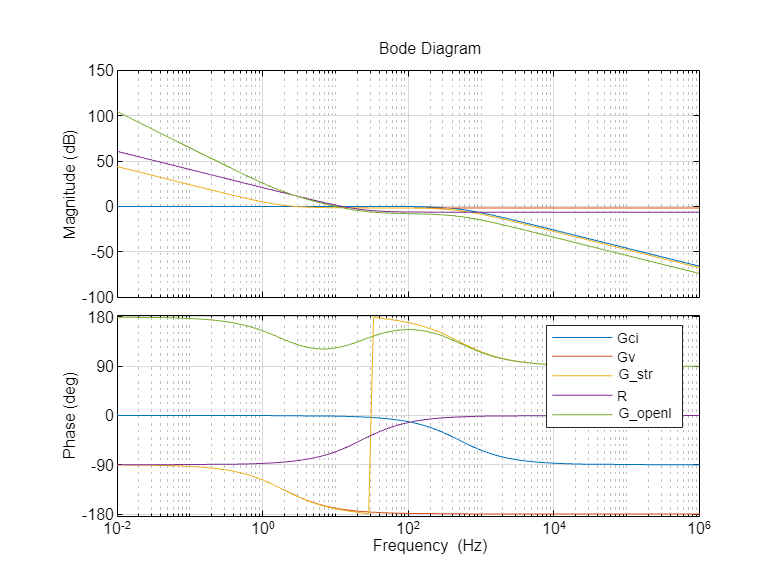


Gu=(3/2*UNd-s*L*P0/UNd)/(s*UDC*C);
Gstr=Gapprox*Gu;


kpu=0.479;
Tnu=0.007;
Gcu=kpu*(1+s*Tnu)/(s*Tnu);

Golu=Gcu*Gstr;
Gclu=Golu/(1+Golu); 

figure(3);
bode(Gapprox, Gu, Gstr,Gcu,Golu,options);
legend('Gci', 'Gv', 'G_{str}','R','G_{openl}');
grid on;

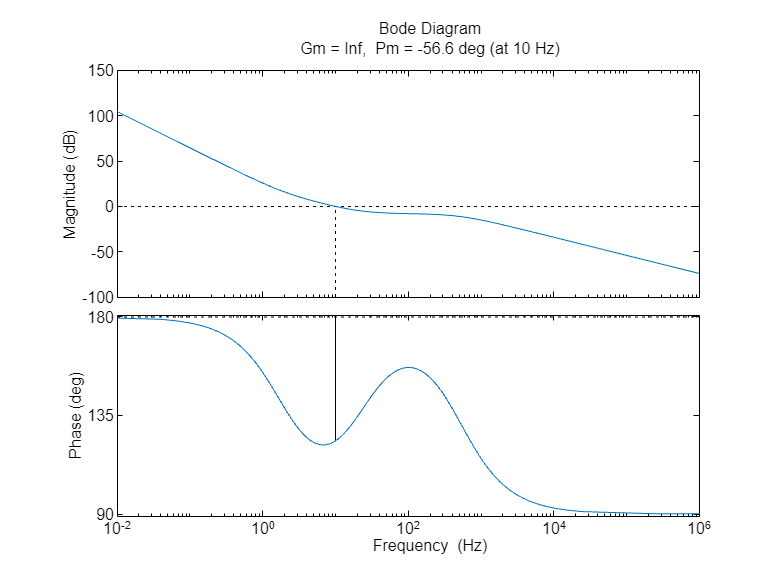

figure(4);
margin(Golu,options)

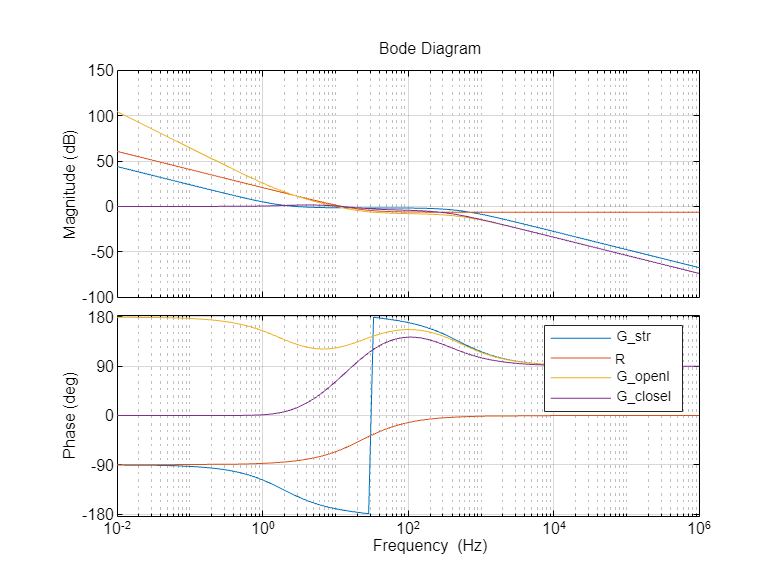

figure(5);
bode(Gstr,Gcu,Golu,Gclu,options);
legend('G_{str}','R','G_{openl}','G_{closel}');
grid on;


Kp_vc =  40 %C_f/Tau_cc % % 0.05%1/Vbase_lv;C_f*omega_v %

Kp_vc = 40

Ki_vc =  200 % 2*Kp_vc*omega_v^2/omega_c% 2*Kp_vc*Tau_cc%    %1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 

Ki_vc = 200


% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
G_vc = Kp_vc + Ki_vc/s

G_vc =
 
  40 s + 200
  ----------
      s
 
Continuous-time transfer function.
Model Properties



G_openl = G_vc*G_cc*G_plant

G_openl =
 
  0.00312 s^2 + 2.416 s + 12
  --------------------------
        3.445e-05 s^3
 
Continuous-time transfer function.
Model Properties


G_cl = G_openl/(1+G_openl)

G_cl =
 
          1.075e-07 s^5 + 8.322e-05 s^4 + 0.0004134 s^3
  -------------------------------------------------------------
  1.187e-09 s^6 + 1.075e-07 s^5 + 8.322e-05 s^4 + 0.0004134 s^3
 
Continuous-time transfer function.
Model Properties



% bode(G_plant,G_cc,G_vc,G_openl,{10e-3,10e5})
% legend('plant', 'cc','vc','openl')
% 
% margin(G_vc)
% bode(G_vc,G_cc,{10e-3,10e5})
% 
% step(G_cl)
% pzmap(G_cl)



% asind((1-200*Tau_cc)/(1+200*Tau_cc))
% sqrt(Ki_vc*1/Tau_cc)
% ans*0.0757204
G_dc = 0.005*Sbase1*(1+0.005*1/s)

G_dc =
 
  7500 s + 37.5
  -------------
        s
 
Continuous-time transfer function.
Model Properties


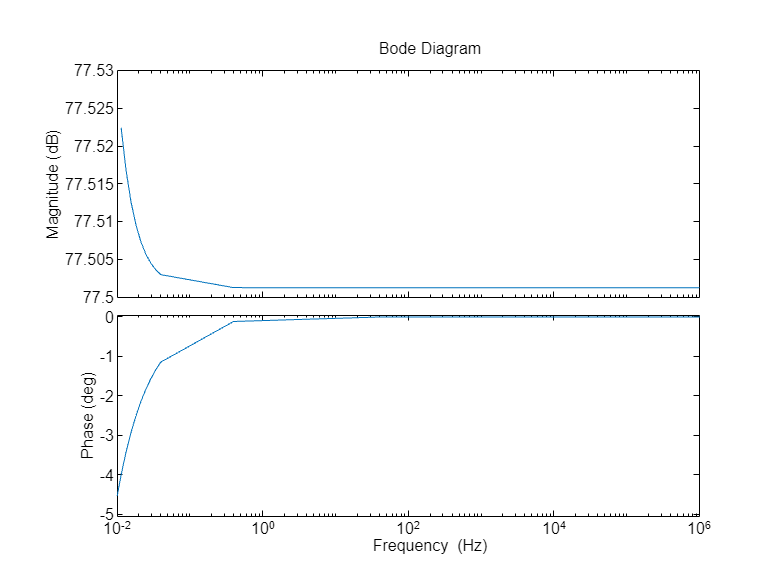

bode(G_dc,options)

% droop control

% (wmeas-wref)/(Pref-Pmeas) = kp_p

    % kp_p = (0.95-1)/(0.5-1)%0.05
    % 
    % % (vmeas-vref)/(Qref-Qmeas) = -kp_q
    % kp_q = (0.9-1)/(0-0.5)

% (5+0.4/s)/(1-5+0.4/s)
% 
% bode((5+0.4/s)/(1+5+0.4/s))
% 

% c_f=0.07
% H=omega_c/2
% tau_dcc = 2*L_f/3*Sbase1/Vbase_lv^2
% G_dc = -(2/C_f)*(tau_dcc*s+1)/s
% G_cc = 1/(0.005*s+1)
% K_v =C_f/2*H/s
% loop_gain = K_v*G_cc*G_dc
% bode(loop_gain)
% margin(H)
% loop_gain/(1-loop_gain)
% margin(loop_gain/(1-loop_gain))
% 
% 
% 1/0.005*2*pi

## dc

% 
% omega_dc = 2*pi*20
% R_dc = V_dc^2/Sbase1
% Kp_dcc = omega_dc*C_dc
% Ki_dcc = omega_dc       
% 
% 
options.PhaseWrapping='off';


ti = 1/f_c

ti = 0.0020

f_dc = f_c/5

f_dc = 100

f_dc*2*pi

ans = 628.3185

G_i_dc = (0.01*s+1)/(s*0.01)

G_i_dc =
 
  0.01 s + 1
  ----------
    0.01 s
 
Continuous-time transfer function.
Model Properties


(1/0.01)/(1/0.01+s)

ans =
 
    100
  -------
  s + 100
 
Continuous-time transfer function.
Model Properties


tau_plant = 2/3*L_f*1*Sbase1/Vbase_lv^2

tau_plant = 0.0835

G_p_dc = -(2/C_f)*(tau_plant*s+1)/s

G_p_dc =
 
  -2.205 s - 26.41
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


G_dc_plant = G_i_dc*G_p_dc

G_dc_plant =
 
  -0.02205 s^2 - 2.469 s - 26.41
  ------------------------------
             0.01 s^2
 
Continuous-time transfer function.
Model Properties


ks = 225        

ks = 225

ki = 1

ki = 1

Gdc = -ks/s

Gdc =
 
  -225
  ----
   s
 
Continuous-time transfer function.
Model Properties


G_dc_openl = Gdc*G_dc_plant

G_dc_openl =
 
  4.962 s^2 + 555.6 s + 5943
  --------------------------
           0.01 s^3
 
Continuous-time transfer function.
Model Properties


n0 = 1/(10^(-23/20))

n0 = 14.1254


a = 200

a = 200

p = sqrt(a)*2*pi*f_dc

p = 8.8858e+03

N = n0*(s+p/a)/(s+p)

N =
 
  14.13 s + 627.6
  ---------------
     s + 8886
 
Continuous-time transfer function.
Model Properties


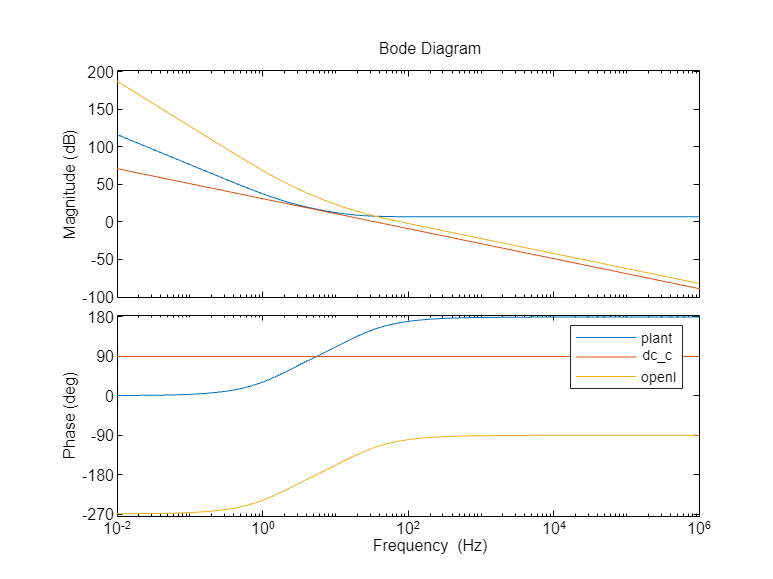


bode(G_dc_plant,Gdc,G_dc_openl,options)
legend('plant', 'dc_c','openl')

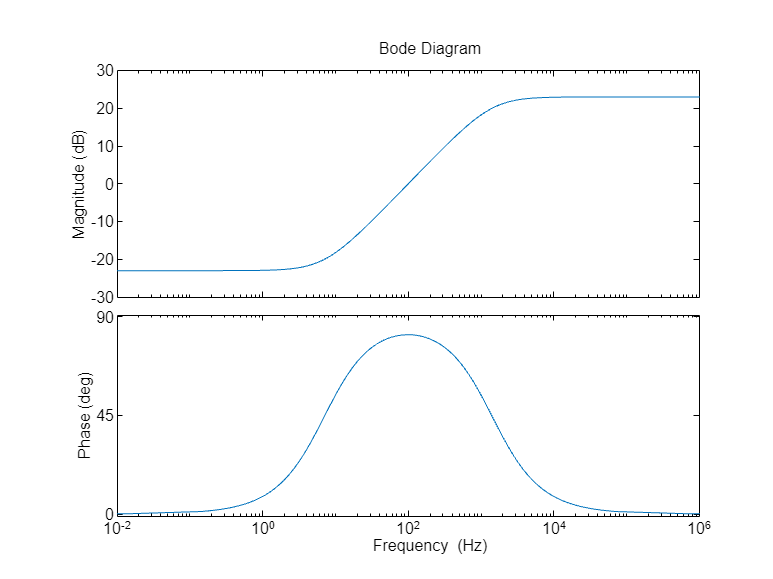

bode(N,options)

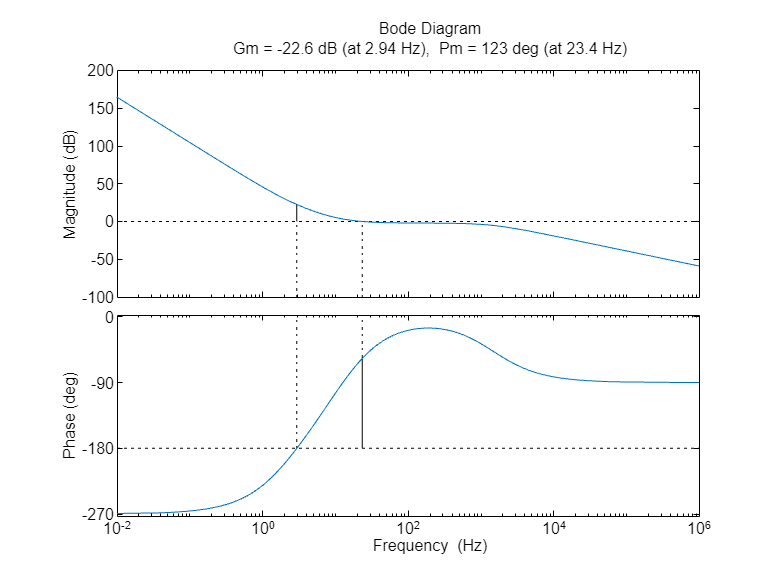

margin(N*G_dc_openl,options)

N*G_dc

ans =
 
  1.059e05 s^2 + 4.707e06 s + 2.353e04
  ------------------------------------
              s^2 + 8886 s
 
Continuous-time transfer function.
Model Properties
